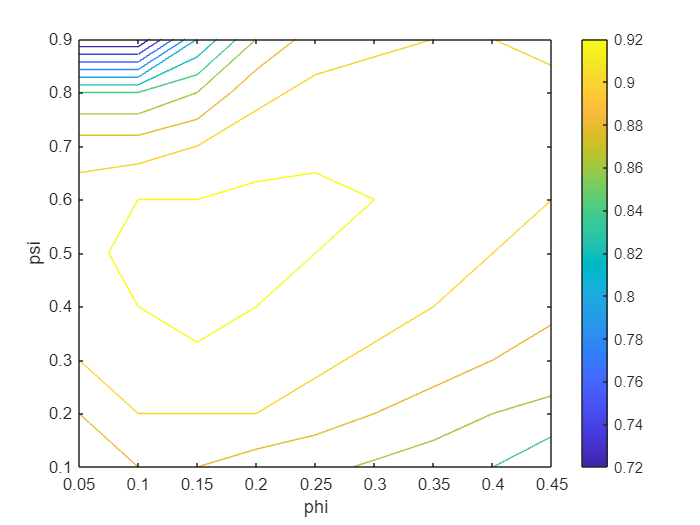

clear all
close all
clc

filename = "Smith_Chart.txt";
dataLines = [1 inf];
SmithChart = importfile(filename, dataLines);
phi = 0.05:0.05:0.45;
psi = 0.1:0.1:0.9;
n = 1;
for i = 1:size(phi,2)
    for j = 1:size(psi,2)
        eta(i,j) = SmithChart(n,3);
        n = n+1;
    end
end
[PHI,PSI] = meshgrid(phi,psi);
contour(PHI,PSI,eta)
xlabel("phi")
ylabel("psi")
colorbar

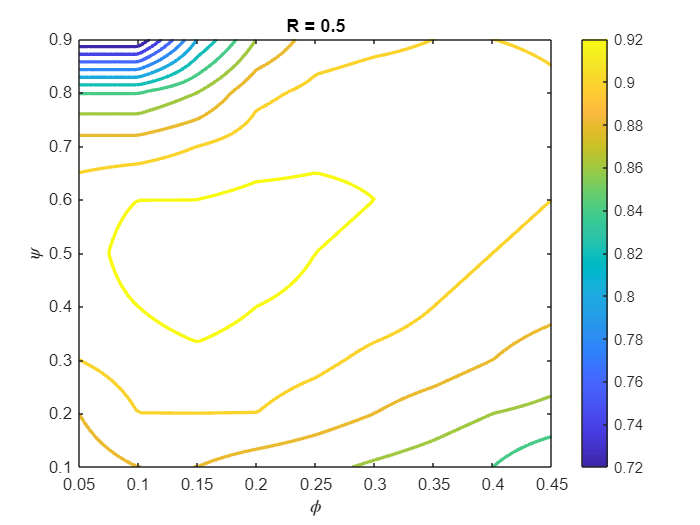


phiq = linspace(0.05,0.45);
psiq = linspace(0.1,0.9);
[PHIQ,PSIQ] = meshgrid(phiq,psiq);
etaq = interp2(phi,psi,eta,PHIQ,PSIQ);
%etaqv = interp2(phi,psi,eta,phiq,psiq);

contour(PHIQ,PSIQ,etaq,"LineWidth",2)
title("R = 0.5")
xlabel("$\phi$","Interpreter","latex")
ylabel("$\psi$","Interpreter","latex")
colorbar

fid = fopen("Smith_Chart_file.txt","w");
for i = 1:size(etaq,1)
    for j = 1:size(etaq,2)
        fprintf(fid,"%f %f %f \n",PHIQ(i,j),PSIQ(i,j),etaq(i,j));
    end
end
fclose(fid);